# 1.3.02 Задача switch-case и if-else

Необходимо написать алгоритм, который зажигает нужный сигнал светофора в зависимости от его текущего состояния: Движение разрешено, Внимание и Стоп.

## Подготовка

% Очищаем текущую фигуру
close gcf
% Считываем изображение из текущей папки
im=imread('traffic.jpg');
% Строим изображение в исходном масштабе
p=image(im);
p.Parent.PlotBoxAspectRatio = [1,1,1];
set(gcf,'Resize','off')
set(gca,'HitTest','off')
hold on
% Координаты центров ламп нам известны
xCenter = 401;
yGreen = 636;
yYellow = 426;
yRed = 215;
% Закрасим их черным цветом
plot([xCenter xCenter xCenter],...
    [yGreen yYellow yRed],...
    'LineStyle','none',...
    'Marker','o',...
    'MarkerFaceColor','black',...
    'MarkerSize',50,...
    'MarkerEdgeColor','black')


## Реализация (`switch-case`)

В переменную `state` мы будем записывать текущее состояние светофора

state = 'Движение разрешено';% 'Движение разрешено','Внимание','Стоп'

Реализуйте логику включения нужной лампы с помощью конструкции `switch-case`. Для реализации логики нужно указать координату `y` лампы и ее цвет `Color`.

`y` принимает значения: `yGreen`, `yYellow`, `yRed`.

`Color` принимает значения: `'green'`, `'yellow'`, `'red'`.

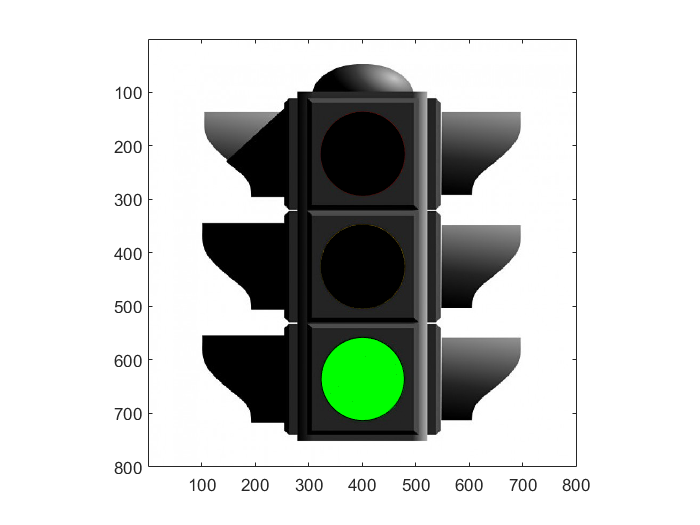

% Зажигаем нужный цвет (switch-case)
switch state
    case 'Движение разрешено'
        y = yGreen;
        Color = 'green';
    case  'Внимание'
        y = yYellow;
        Color = 'yellow';
    case 'Стоп'
        y = yRed;
        Color = 'red';
    otherwise
        y = yGreen;
        Color = 'black';
end
plot(xCenter,y,'Marker','o','MarkerFaceColor',Color,'MarkerSize',50,'MarkerEdgeColor','black')

## Реализация (`if-else`)

Повторите ту же логику, но с помощью конструкции `if-else`

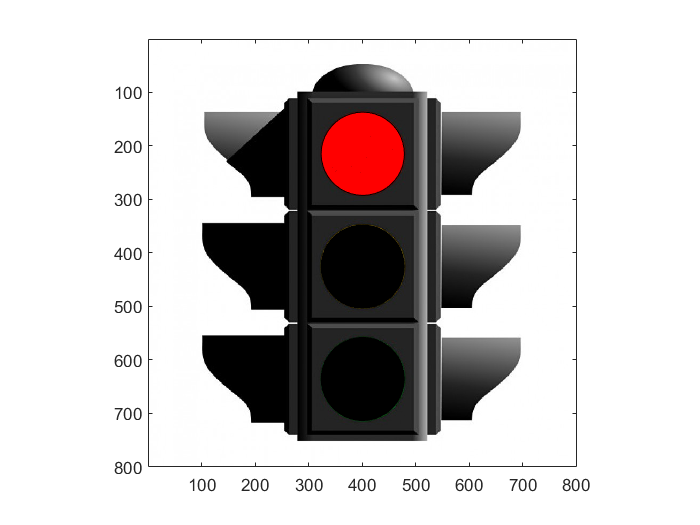

% Подготовка
close gcf
im=imread('traffic.jpg');
p=image(im);
p.Parent.PlotBoxAspectRatio = [1,1,1];
set(gcf,'Resize','off')
set(gca,'HitTest','off')
hold on
xCenter = 401;
yGreen = 636;
yYellow = 426;
yRed = 215;
plot([xCenter xCenter xCenter],...
    [yGreen yYellow yRed],...
    'LineStyle','none',...
    'Marker','o',...
    'MarkerFaceColor','black',...
    'MarkerSize',50,...
    'MarkerEdgeColor','black')

%
state = 'Стоп';% 'Движение разрешено','Внимание','Стоп'
% Зажигаем нужный цвет (if-else)
if strcmp(state,'Движение разрешено')
    y = yGreen;
    Color = 'green';
elseif strcmp(state,'Внимание')
    y = yYellow;
    Color = 'yellow';
elseif strcmp(state,'Стоп')
    y = yRed;
    Color = 'red';
else
    y = yGreen;
    Color = 'black';
end

plot(xCenter,y,'Marker','o','MarkerFaceColor',Color,'MarkerSize',50,'MarkerEdgeColor','black')